# Transverse field Ising model:

# Heat capacity in the mean-field approximation

## Heat capacity in zero field

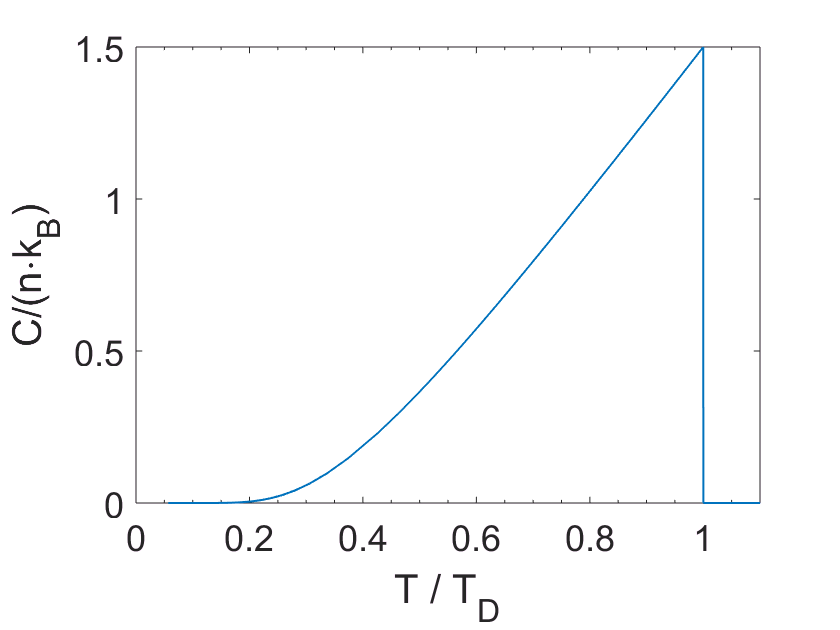

rev_Sz = [logspace(-15,-2),0.01:0.01:0.99];
Sz = 0.5.*(1-rev_Sz);% pseudospin values, with log scale close to Sz,max=0.5
beta = (2./Sz).*atanh(2.*Sz);% beta = 4./temperature 
% (should be 1./T but the factor 4 makes the code simpler)
f = 1/4*(sech(beta.*Sz./2)).^2;% factor appearing in the denominator of 
C_ord = (Sz.*beta).^2.*f./(1-beta.*f);% Cp in the ordered phase
T = [4./beta,1+logspace(-4,0.3,50)];% temperature = 4./beta in the ordered phase
% + log range of values in the disordererd phase T > Tc=1
C = [C_ord,zeros(1,50)];% Cp on the total range of temperatures
figure
plot(T,C)
xlim([0 1.1])
xlabel('T / T_D')
ylabel('C/(n\cdotk_B)')

## Schottky anomaly above the critical field

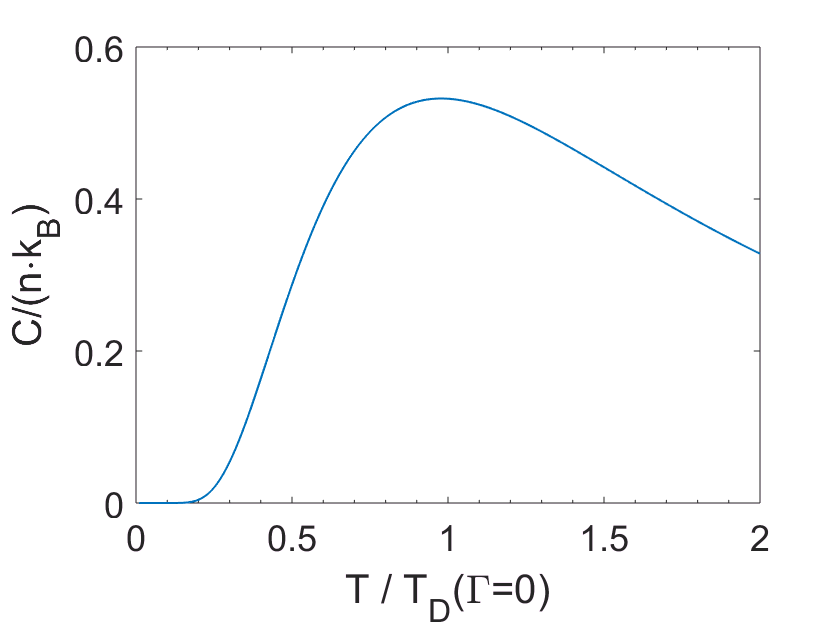

gamma_abv = 1.01;% critical field is gamma = 1
T_abv = 0.01:0.01:2.00;
beta_abv = 4./T_abv;
figure
hold on
for xabv = gamma_abv
    HT_ratio = beta_abv.*xabv./2;% dimensionless product appearing in
    C_abv = 0.5.*(HT_ratio).^2.*sech(HT_ratio);% the expression of the Schottky anomaly
    plot(T_abv,C_abv)
end
xlabel('T / T_D(\Gamma=0)')
ylabel('C/(n\cdotk_B)')

## Compute heat capacity under transverse field

gamma = [0.4,0.6,0.8,0.9,0.95];% transverse field; the critical field is gamma = 1
lgth = 199;% length of arrays Cf and Tf
T_field = T;% first set of data is for gamma = 0
C_field = C;% taken from calculation in zero field (see above)
rev_Szf = [logspace(-15,-2),0.01:0.01:0.99];% values of the pseudospin
Sz_full = 0.5.*(1-rev_Szf);% range from 0 to 0.5 under zero transverse field
beta_full = (2./Sz_full).*atanh(2.*Sz_full);% corresponding values of beta=1/temperature
for x = gamma
    Tc = x./atanh(x);% normalized transition temperature
    
    beta_ordf = beta_full(4./beta_full<Tc);% MF Cp is only valid inside the ordered phase
    Szf = Sz_full(4./beta_full<Tc);% defined such that T=1/beta < Tc
    f = 1/4*(sech(beta_ordf.*Szf./2)).^2;% factor appearing in the denominator of 
    C_ordf = (Szf.*beta_ordf).^2.*f./(1-beta_ordf.*f);% Cp in the ordered phase

    rg_abvf = logspace(-4,0.3,lgth-length(beta_ordf));
    T_abvf = 4./beta_ordf(end)+rg_abvf;
    beta_abvf = 4./T_abvf;
    HT_ratio = beta_abvf.*x/2;% dimensionless product appearing in
    C_abvf = 0.5.*(HT_ratio).^2.*sech(HT_ratio);% the expression of the Schottky anomaly

    Tf = [4./beta_ordf,T_abvf];
    % range of temperatures in the ordered phase: 4/betaf
    % and in the disordered phase from Tc to 2K (10^0.3=2)
    Cf = [C_ordf,C_abvf];% Cp on the full range of Tf
    % plot(4./betaf,C_ordf)
    T_field = [T_field ; Tf];
    C_field = [C_field ; Cf];
end
T_field;
C_field;

## Plot heat capacity under transverse field

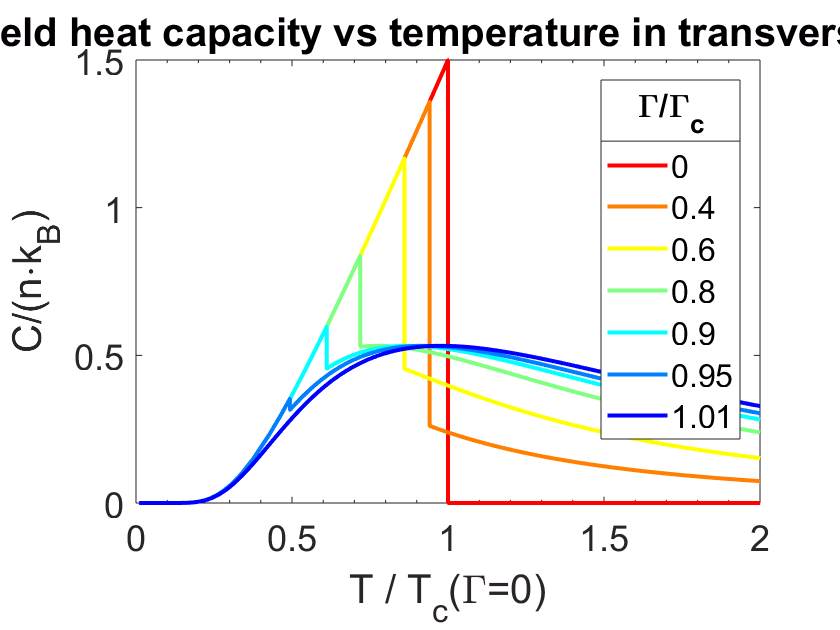

N = size(T_field,1);% number of data sets at constant fields below the critical field
colour = jet(2*N+1);% set up a nice color spectrum for all data sets, 
% including that above the critical field
% Using a palette of more than 10 rows is necessary in order to include red and blue
% A total of 13 rows is very good; hence the argument 2*N+1 instead of just N
figure()
hold on
for i = 1:N
    plot(T_field(i,:),C_field(i,:),'color',colour(2*(N+1-i)+1,:),'linewidth',2)
end
plot(T_abv,C_abv,'color',colour(1,:),'linewidth',2)% See section 'Schottky anomaly above the critical field'

xlim([0 2])
ylim([0 1.5])
legendCell = ['0';cellstr(num2str(gamma','%-.2g'));num2str(gamma_abv')];
% first curve is in zero field, central ones are for varying gamma, last is above critical field
hleg = legend(legendCell);
htitle = get(hleg,'Title');
set(htitle,'String','\Gamma/\Gamma_c')
title('Mean-field heat capacity vs temperature in transverse fields \Gamma')
xlabel('T / T_c(\Gamma=0)')
ylabel('C/(n\cdotk_B)')

## TFIM Mean-field Phase boundary 

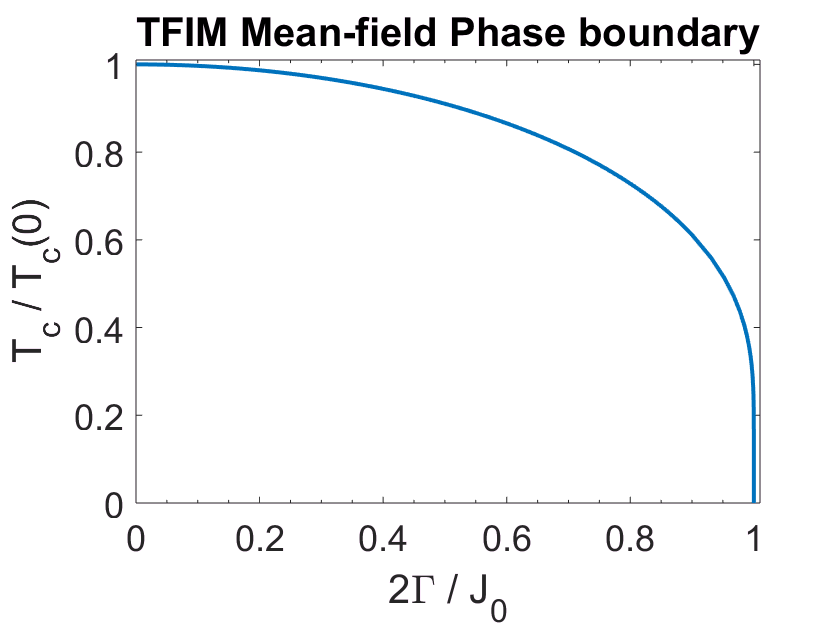

rev_x = [logspace(-17,-1,100),0.109:0.01:0.999];
x = 1-rev_x;
% create an x axis that approches 1 with arbirtrarily small values 
% in order to be able to plot the vertical part of the phase boundary
% and does not start from 0 since y(0) is also not defined
y = x./atanh(x);% defined for 0 < x < 1
plot(x,y,'linewidth',2);
xlim([0 1.01])
ylim([0 1.01])
ylabel('T_c / T_c(0)')
xlabel('2\Gamma / J_0')
title('TFIM Mean-field Phase boundary')